Linear Sensory Recalibration Model of Implicit Adaptation. 

Mengzhan Liufu, Jingyue Xu, Xueqian Deng, Chen Yang. Jan. 14 2022. 

Adapted from Hadjiosif, A. M., Krakauer, J. W., & Haith, A. M. (2021). Did We Get Sensorimotor Adaptation Wrong? Implicit Adaptation as Direct Policy Updating Rather than Forward-Model-Based Learning. *The Journal of Neuroscience*, *41*(12), 2747–2761. [https://doi.org/10.1523/JNEUROSCI.2125-20.2021](https://doi.org/10.1523/JNEUROSCI.2125-20.2021)

To see how simulated mirror-reversal adaptation varies with the width (σ) and learning rate (η) of the basis functions, and the saturation limit (A), select these parameters and click "Simulate". 

# Simulate Sensory Recalibration Model of Implicit Adaptation. 

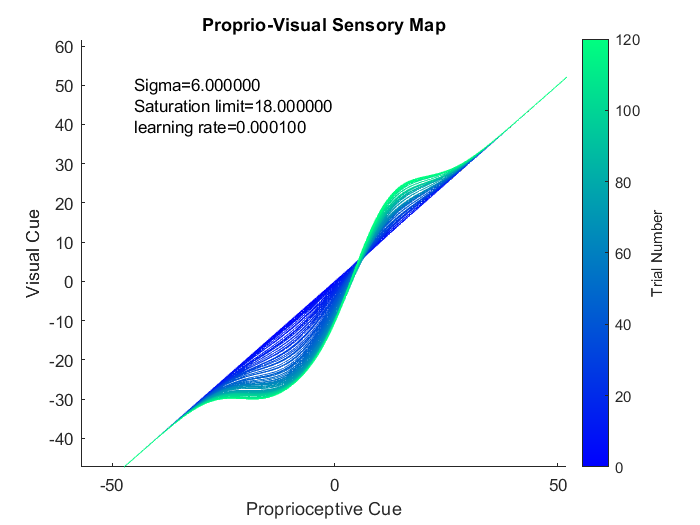

%Specify width of basis function
sigma =6;
eta =0.0001;
sat_limit =18;
seed_rng =48;
 

sigma_noise = 2;
txt = sprintf('Sigma=%f\nSaturation limit=%f\nlearning rate=%f',sigma,sat_limit,eta);
rng (seed_rng); % fix randomization so simulations are reproducible

% initiate basis functions
delta_c = 0.05;
c = -60:delta_c:60;
priop = -60:.5:60; 
w = zeros(size(c));
% proprio is the kernel of proprioception

% Learning (note that Ntrials is more than needed to simulate Experiment 2,
% which is 24 cycles (168 trials, i.e. 7 targets x 24 trials; and steady-state
% analysis uses cycles 13:24)
Ntrials = 120;

[u_out,y_out,te] = deal(NaN(1,Ntrials));

root_dir = pwd;
% Load targets used in experiments
cd('RawData\');
vision = cell2mat(struct2cell(load("targetdata210trials.mat")));
cd(root_dir);
vision = vision(1:120);
possibleivusalgoals = [-12;-9;-6;-3;0;3;6;9;12;15];
w_sat_limit = sat_limit*delta_c/sigma/sqrt(2*pi);

%basis functions
B = NaN(length(c),length(priop));
for i=1:length(c)
    B(i,:) =  exp(-(priop-c(i)).^2/(2*sigma^2));
end

priop_map = NaN(Ntrials,length(priop));
absoluteerror = [0 0];
signederror = [0 0];
for i=1:Ntrials
    priop_map(i,:) = priop + sigmoid_saturation(w,w_sat_limit)*B;
    % current map
    
    [~,i_t] = min((priop-vision(i)).^2);
    %supposedly output
    
    priopout(i) = priop_map(i,i_t) + sigma_noise*randn;
    %add randomness
    
    % apply perturbation
    onlinecursor(i) = - priopout(i); % mirroring
    [~,i_thokin] = min((priop-onlinecursor(i)).^2);
    prioprime(i) = priop_map(i,i_thokin) + sigma_noise*randn;
    
    [~,i_selected] = min(abs(priop-vision(i)));
    
    %priop error
    prioperror(i) = -(prioprime(i) - priopout(i));
    
    % Absolute and signed Error
    absoluteerror(i) = abs(onlinecursor(i) - priopout(i));
    signederror(i) = onlinecursor(i) - priopout(i);
    
    % learning update
    w = w + eta*prioperror(i)*B(:,i_selected)';
end

lins = lines;
figure; hold on;
mycolor = colormap("winter");
%mycolor = colormap("jet");
%mycolor=mycolor(1:Ntrials,:);
xlim_right = 60;
ylim_up = 60;
plot(linspace(-80,80,161),linspace(-80,80,161),'--','color','black');
for i = 1:Ntrials
    plot(linspace(-60,60,241),priop_map(i,:),'color',mycolor(round(i*(length(mycolor)/Ntrials)),:));
end
xlim([-xlim_right,xlim_right]);
ylim([-ylim_up,ylim_up]);
title('Proprio-Visual Sensory Map');
text(15-xlim_right,ylim_up-15,txt);
caxis([0,Ntrials]);
c=colorbar;
c.Label.String = 'Trial Number';
xlabel('Proprioceptive Cue');
ylabel('Visual Cue');

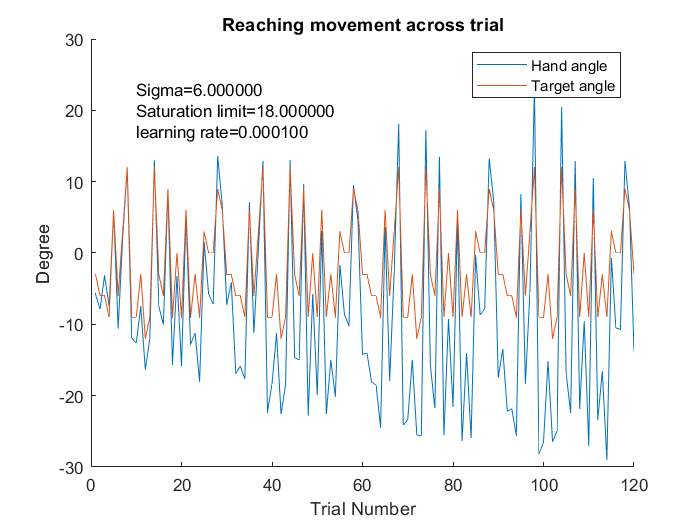

figure;hold on;
xlabel('Trial Number');
ylabel('Degree');
plot(priopout);
plot(vision);
text(10,20,txt);
title('Reaching movement across trial');
legend('Hand angle','Target angle')

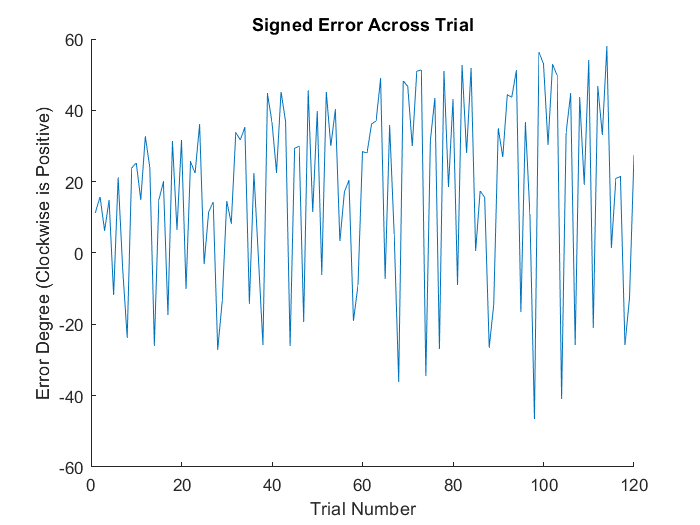

figure; hold on;
plot(signederror);
xlabel('Trial Number');
ylabel('Error Degree (Clockwise is Positive)');
title('Signed Error Across Trial')

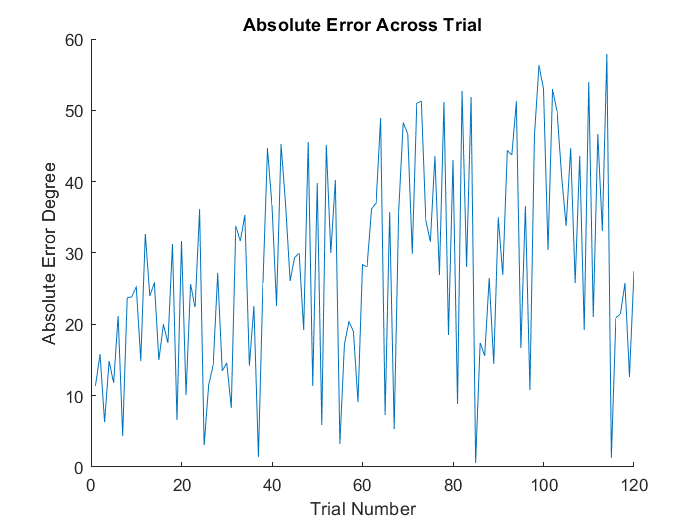

figure; hold on;
plot(absoluteerror);
xlabel('Trial Number');
ylabel('Absolute Error Degree');
title('Absolute Error Across Trial');

function y = sigmoid_saturation(x,sat_limit)

y = sat_limit*erf(sqrt(pi)/2*x/sat_limit); end